Consider the confound of sex.

group1: ratio of numbers of males between sites

group2: ratio of numbers of females between sites

sumGroup: ratio of numbers of subjects between sites

group1vsGroup2: ratio of (male/female) between sites

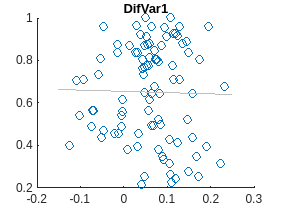

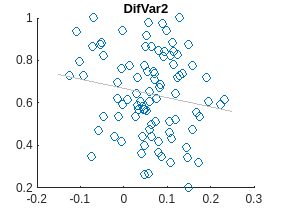

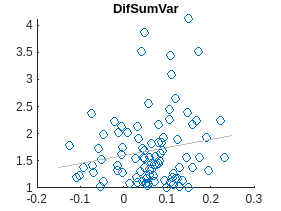

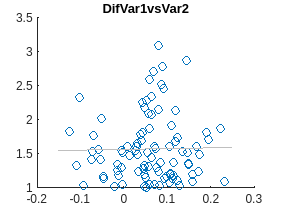

BD


                      group1       group2     sumGroup    group1vsGroup2
                     _________    ________    ________    ______________

    spearman corr    -0.019353    -0.10077    0.10047       -0.009492   
    p                  0.47729     0.25674    0.23727         0.44626   



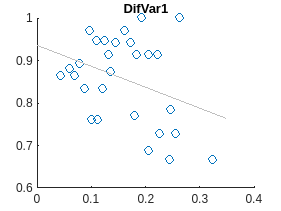

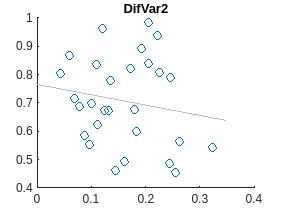

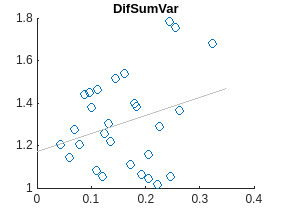

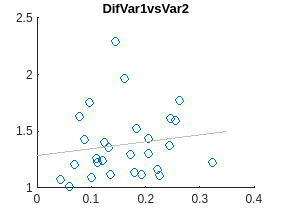

SCA


                      group1      group2     sumGroup    group1vsGroup2
                     ________    ________    ________    ______________

    spearman corr    -0.18521    -0.15326    0.10892        0.24576    
    p                 0.23686     0.19782    0.29741        0.19487    



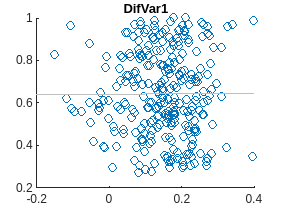

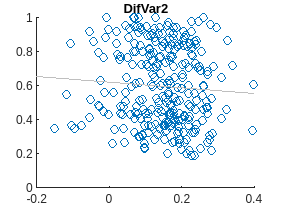

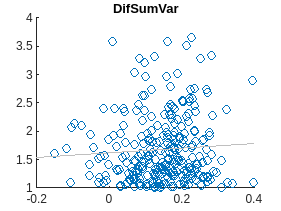

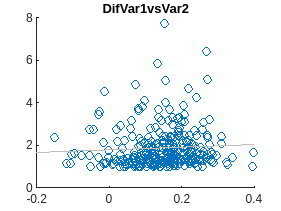

SCZ


                       group1       group2      sumGroup    group1vsGroup2
                     __________    _________    ________    ______________

    spearman corr    -0.0068071    -0.089068    0.061431        0.1292    
    p                   0.49085      0.13251     0.24087       0.12633    



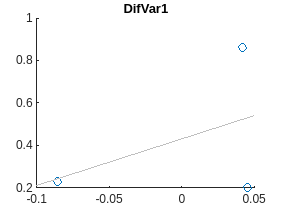

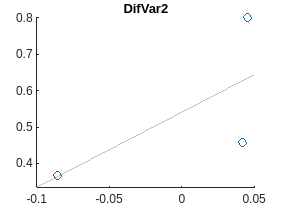

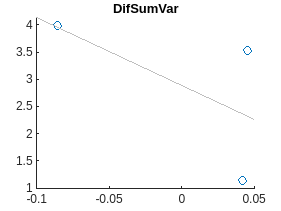

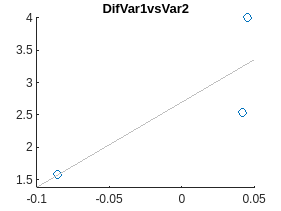

ASD


                     group1      group2      sumGroup    group1vsGroup2
                     _______    _________    ________    ______________

    spearman corr       -0.5            1       -0.5               1   
    p                0.33576    4.885e-15    0.32356       4.885e-15   



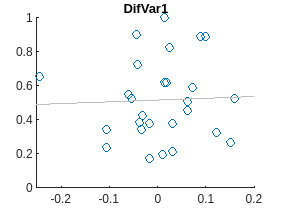

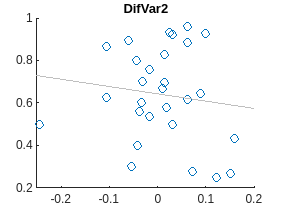

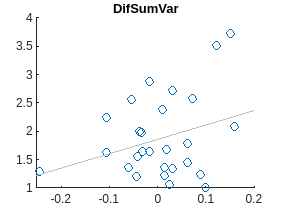

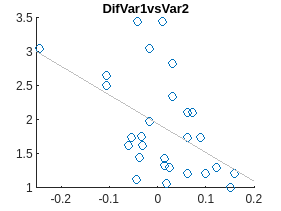

MDD


                     group1      group2      sumGroup    group1vsGroup2
                     _______    _________    ________    ______________

    spearman corr    0.02739    -0.094156    0.14067        -0.43788   
    p                0.45113      0.38535    0.25318        0.017958   



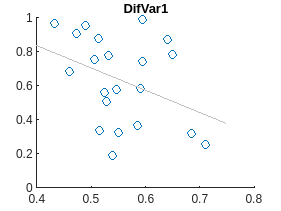

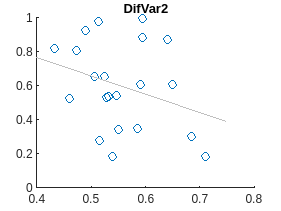

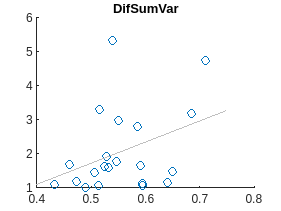

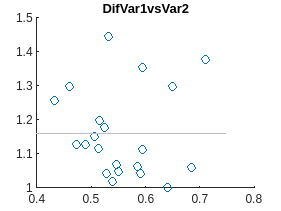

AD


                      group1      group2     sumGroup    group1vsGroup2
                     ________    ________    ________    ______________

    spearman corr    -0.36364    -0.23117    0.30909        -0.16753   
    p                 0.15362     0.24956    0.17934         0.29657   



% Clear workspace and close all figures
clear all
close all

% Define parameters
iCOMBAT = 1; % Flag for applying COMBAT harmonization
smoothKernel = 10; % Smoothing kernel size
iter = 5000; % Number of iterations for Mantel test
hemi = 'lh'; % Hemisphere (e.g., left hemisphere)
type = 'spearman'; % Type of correlation (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata (scanner information)
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataSBM_extended.csv'], 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site information
load(['output/corr_zmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '_', hemi, '_all.mat'], ...
    'map', 'corDiag',  'siteList');

% Initialize variables for results
varTable = cell(nDiag, 1);
nSite = cell(nDiag, 1);

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to sex number similarity between sites
    [varTable{iDiag}, maleRatio{iDiag}, femaleRatio{iDiag}, subjectRatio{iDiag}, maleFemaleRatio{iDiag}, nSite{iDiag}] = cor_var_sex(metadata, diagnosisString(iDiag), corDiag{iDiag},siteList{iDiag}, iter, type);
% Display results for the current diagnosis
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag)))
        disp(varTable{iDiag})
        disp(' ')
        disp(' ')
    end
end

% Suppress warnings related to the last operation
warning('off', 'last');

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.


% Save results to a .mat file
save('output/confound_sex.mat','varTable',  'maleRatio', 'femaleRatio', 'subjectRatio', 'maleFemaleRatio','nSite')